# EEET-425 Digital Signal Processing Lab 08 Equalizer Lab  (One week -- IEEE Format not required)

**This lab will focus on two topics, developing an equalizer to compensate for the LM61 temperature sensor time response and performing convolution in the time domain.**

**Throughout the semester you have been working with the LM61 temperature sensor as part of the breathing rate detection system that you will build as your final project.  The LM61 sensor converts the temperature of the sensor to an analog voltage with a linear response.  The Arduino system converts the analog voltage to a digital word for later processing.**

**The sensor itself does not immediately respond to change the output voltage for an immediate change in the ambient temperature.  The output of the sensor lags behind the temperature change.  The sensor essentially acts like a circuit with a very slow time constant.  Another way to think of this is that the temperature change is subjected to a very low frequency low pass filter.  The step response of a very low frequency low pass filter is a slow exponential response.  Think of the response of an Resistor/Capacitor (RC) lowpass filter with a very low corner frequency.**

**In the breathing rate detection system, which includes the dither circuit and the LM61 temperature sensor we are trying to detect breathing at different rates.  The output of the sensor will look somewhat sinusoidal as the patient breaths in and out.  Since the response of the sensor is a low frequency response the magnitude of the sinewave will be attenuated as the rate of breathing increases.  You may have seen this if you were breathing too rapidly in some of the lab experiments.  The output variation wasn’t as large as when you breathed very slowly.  In Figure 1 below, I collected temperature data for breathing on the sensor at different rates of 5 breaths per minute (BPM), 18 BPM and 49 BPM. ** 

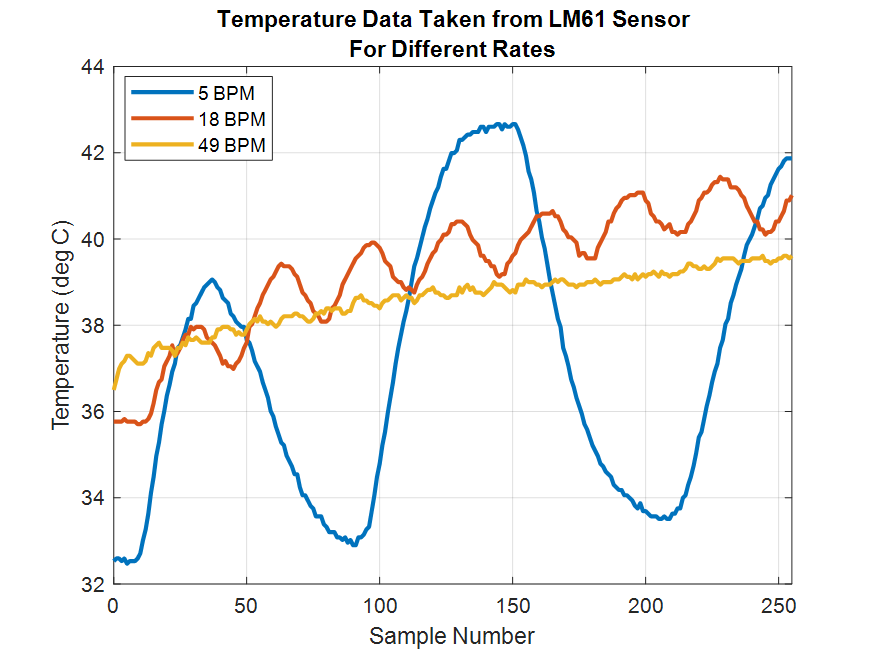                              

***Figure 1 The temperature variation decreases as the breathing rate increases.  An initial drift also occurs at the beginning of the measurement.***

## Part 1 -- The "Leaky " Integrator

**The amount of ****variation**** in the temperature decreases as the breathing rate increases.  This is due to the low pass effect of the temperature sensor.**

**Our goal is to be able to distinguish low breathing rates from high breathing rates so we would like that the sensor responds the same to fast breathing as it does to slow breathing, but it doesn’t.  Fortunately, there is a way to compensate for the sensor’s low frequency response.**

**The low frequency response of the sensor can be thought of almost as an integrator.  In fact, its response is often referred to as a “leaky” integrator.  **

**The inverse function of integration is differentiation.  If we take the output of an integrator and then differentiate it, we get back the original input signal.  **

**In the discrete time domain, integration involves summing up values of samples over time.  A differentiator can be created by taking the difference between every other sample.  These are both linear operations and can be thought of in terms of their impulse responses.  **

**The impulse response of the ****pure ****integrator is **$h_{int}[n]=[1,1,1,1,1,...]$**.  Theoretically it extends to infinity in time.  The system sums up all the values of all the samples in the sequence.  We can perform the integration recursively as well.  This is expressed in the difference equation:**

##  
$$y_k = x_k+ y_{k-1}$$


**An approximation to the integrator is the “leaky” integrator which can be described by the difference equation:**

##  
$$y_k = (1-\alpha)x_k + \alpha y_{k-1}$$


**The value of **$\alpha$**  determines the response of the system.  The closer **$\alpha
$**  is to 1 the closer to the pure integrator it becomes.**

**The file 'leakyIimpulse.mat' contains an impulse response for a leaky integrator.  The impulse response data is truncated so it doesn't represent the true impulse response which is infinite in length.**

**Load the 'leakyImpulse.mat' file and plot the impulse response.  Then find the frequency response of the filter by taking the FFT of the impulse response.  There are 256 samples in the impulse response.  The result of the FFT is a sequence of complex samples in the frequency domain that range from 0 to the sample rate.  The MATLAB command fft( x ) will compute the fft of the variable x.  The result is a complex value.  The magnitude of a complex value is found by using the MATLAB command abs( y ).  To convert to decibels use 20*log10( X ).**

**It is convenient to plot the frequency in breaths per minute. The system we are using is sampling at 100 mSec per sample or a rate of 10 Hz.  To convert from the sample number of the FFT to breaths per minute use the following relationship**

## 
$$bpm = \frac{n}{N}\times 10Hz\times 60\frac{sec}{Min}$$


**Where 'n' is a vector of sample numbers and 'N' is the total number of samples.**

**You many want to create a variable that represents the frequency in Breaths per Minute from the sample number to use for your X variable in plots.  In MATLAB to create a variable 'n' with 256 values representing the sample numbers from 0 to 255 use the colon operator**

## 
$$n= (0:1:255);$$


**Because the increment is 1, this can be further simplified to:**

## 
$$n = (0:255);$$


**Then convert the variable to BPM using the equation above.**

**Plot the magnitude of the frequency response in decibels versus frequency in Breaths per Minute.  Plot only from 0 to 50 Breaths per minute**

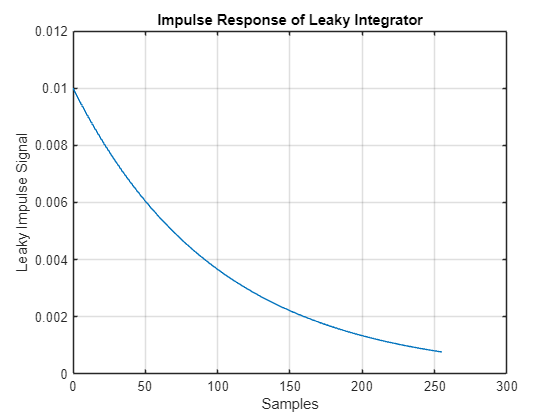

%  Load the file with the impulse response 'leakyImpulse.mat'.  This loads
%  a variable named leakyImpulse into the workspace.  The first column is
%  the sample number, the second column is the impulse response
%
%  Plot the impulse response of the leaky integrator
%


% SOLUTION
clc; clear; close all
load('data/leakyImpulse.mat')
sample = leakyImpulse(:,1);
leakyImpResponse = leakyImpulse(:,2);

figure
plot(sample, leakyImpResponse)
title("Impulse Response of Leaky Integrator")
ylabel("Leaky Impulse Signal")
xlabel("Samples")
grid on

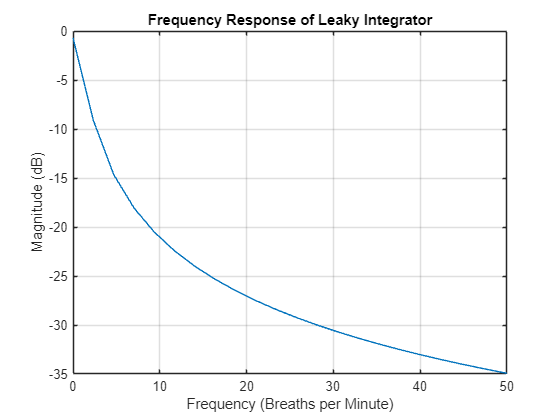


%  Create a variable that converts the sample number to the frequency in
%  breaths per minute.  Then find the FFT of the impulse response.  Compute
%  the magnitude of the frequency response in decibels using 20*log10( X ).
%  Plot the frequency response from 0 to 50 BPM  (look up the xlim or axis
%  command).

%  SOLUTION
N  = 256;          % Number of samples
Fs = 10;           % Sampling rate (Hz)
n  = 0:N-1;        % Sample indices

% Convert sample index to BPM
freqBPM = n * (60 * Fs / N);

% Compute the FFT of the impulse response
Y = fft(leakyImpResponse, N);

% Compute magnitude in dB
magnitudeResponse_dB = 20 * log10(abs(Y));

% Plot the frequency response (0 to 50 BPM)
figure;
plot(freqBPM, magnitudeResponse_dB);
title('Frequency Response of Leaky Integrator');
xlabel('Frequency (Breaths per Minute)');
ylabel('Magnitude (dB)');
xlim([0 50]); grid on;  % Show only 0 to 50 BPM

### Question 1

**Describe the impulse response of the leaky integrator.  How would this compare to a perfect integrator?  Why is it referred to as a leaky integrator?**

The impulse response of the leaky integrator slowly decays over time, hence the name 'Leaky Integrator'. A perfect integrator would have the impulse response increase over time.

### Question 2

**Describe the frequency response of the leaky integrator.  How does this compare to a single pole low pass filter response?**

The frequency response of the leaky integrator acts as a low pass filter in which only the lower frequnecies are going through.  This compares to a single pole low pass filter because as the gain is cut decreases as the frequency increases.

## Part 2 -- The Equalizer

**The response of the integrator needs to be compensated.  A system called an equalizer can compensate for the integrator response.  The equalizer to compensate for the integrator is a differentiator.**

**The differentiator can compensate for the response of the leaky integrator.  A simple first order differentiator takes the difference between adjacent samples of the input signal.  It can be described by the following impulse response:**

##  
$$h_{diff}=[-1,1]$$


**Create a variable with the impulse response of the differentiator.  Find the FFT of the differentiator impulse response.  You can compute an FFT to any length by adding a second argument to the function that is the desired length.  For example to compute the FFT of the variable y at a length of 256 use the syntax Y = fft( y, 256 ).**

**Plot the frequency response (in decibels) of the differentiator from 0 to 50 BPM**

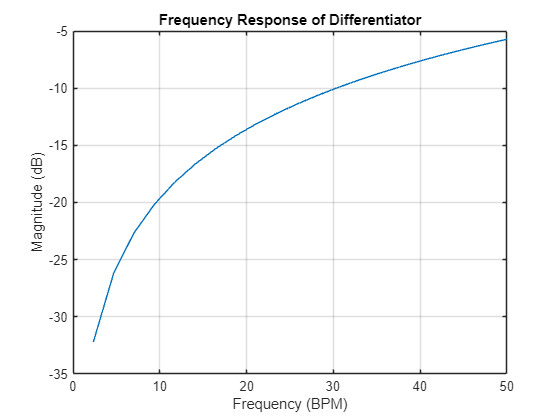

%  Create a variable that is the impulse response of the differentiator.
%  Then find the FFT of the impulse response using a length of 256 to match
%  the leaky integrator length.
%  Plot the frequency response of the differentiator from 0 to 50 BPM


%  SOLUTION
% Create a variable that is the impulse response of the differentiator
diffImpResponse = [-1 1];

% Compute the FFT of the differentiator with length 256
hFFT = fft(diffImpResponse, 256);

% Compute magnitude in dB
hMagnitude = 20 * log10(abs(hFFT));

% Generate frequency axis in BPM
N = 256; % FFT length
fs = 10; % Given sampling frequency in Hz
freqHz = (0:N-1) * (fs / N); % Frequency in Hz
freqBPM = freqHz * 60; % Convert Hz to BPM

% Plot the frequency response of the differentiator
figure
plot(freqBPM(1:N/2), hMagnitude(1:N/2)) % Only plot positive frequencies
xlim([0 50]) % Limit x-axis to 0-50 BPM
title("Frequency Response of Differentiator")
xlabel("Frequency (BPM)")
ylabel("Magnitude (dB)")
grid on

### Question 3

**Describe the frequency response of the differentiator.  How would this work to compensate for the frequency response of the temperature sensor?**

The frequency response of the differentiator allows higher frequencies to pass, similar to a high pass filter. This could compensate for the frequnecy response of the temperature sensor which acts more like a low pass filter.

## Cascaded Response of the Integrator and Differentiator

**The integrator attenuates higher frequencies and the differentiator enhances higher frequencies.  To see the effect of the differentiator on the leaky integrator we can compute the frequency response of the leaky integrator cascaded with the differentiator we can convolve the two impulse responses.  The length of the convolution of the two responses will be M+N-1 where M is the length of the of the leaky integrator impulse response (256), N is the length of the impulse response of the differentiator (2).  Therefore the result will be **

## 
$$M+N-1 = 256+2-1 = 257$$


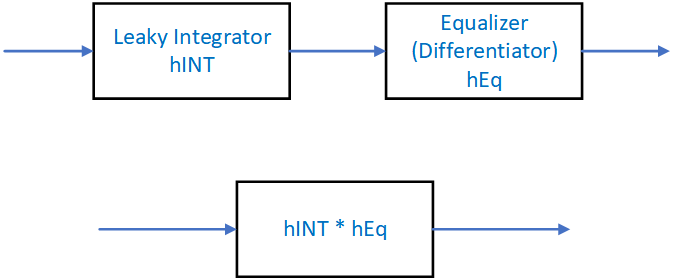

**To convolve two sequences, the MATLAB function conv( x ) can be used.  Plot the impulse response of the cascaded systems along with its frequency response.  Use a length 512 FFT when computing the frequency response.  Since the number of samples has changed you will have to recompute the frequency variable that represents Breaths per Minute.**

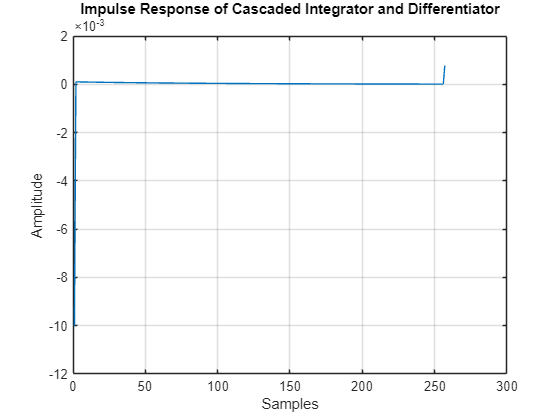

%  Convolve the leaky integrator impulse response and the differentiator
%  impulse response.  
%  
%  Then find the FFT of the cascaded response using a
%  length of 256.
%
%  Plot the frequency response of the cascaded systems
%  in decibels versus frequency in BPM.

%  SOLUTION

% Convolve the leaky integrator and differentiator impulse responses
convResponse = conv(leakyImpResponse, diffImpResponse);

% Compute FFT using a length of 512
N_FFT = 512;
convFFT = fft(convResponse, N_FFT);

% Compute magnitude in dB
convMagnitude = 20 * log10(abs(convFFT));

% Compute frequency axis in BPM
fs = 10; % Given sampling frequency in Hz
freqHz = (0:N_FFT-1) * (fs / N_FFT); % Frequency in Hz
freqBPM = freqHz * 60; % Convert Hz to BPM

% Plot impulse response of cascaded system
figure
plot(convResponse)
title({"Impulse Response of Cascaded Integrator and Differentiator", ""})
xlabel("Samples")
ylabel("Amplitude")
grid on

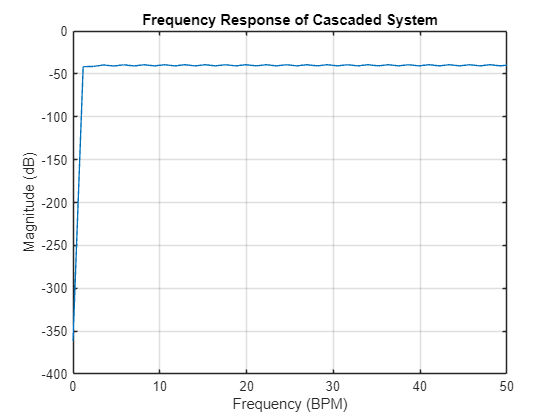


% Plot frequency response of cascaded system
figure
plot(freqBPM(1:N_FFT/2), convMagnitude(1:N_FFT/2)) % Only plot positive frequencies
xlim([0 50]) % Limit x-axis to 0-50 BPM
title("Frequency Response of Cascaded System")
xlabel("Frequency (BPM)")
ylabel("Magnitude (dB)")
grid on

### Question 4

**Describe the frequency response of the cascaded systems.  Has this achieved the desired effect of compensating the response of the temperature sensor?  What other impacts does it have?  What is the response at DC (0 Hz)?**

The frequency response of the cascaded systems ends up flattening out which compensates for the attenuation of the high frequencies caused by the leaky integrator. This achieved the desired effect of effectively compensating for the leaky integrator’s response by flattening the frequency response, ensuring that both fast and slow breathing rates are treated more equally. At 0 Hz the frequency response is completely supressed, ensuring both fast and slow breaths are treated equally.

## A Modified Equalizer

**One additional advantage of using the differentiator as an equalizer is that the response at 0 Hz or DC is highly attenuated.  This will help to remove the impacts of slow drift and the variation of average temperature of the patients breathing.  The breathing ****rate**** can now be the sole focus.**

**A disadvantage of the first order differentiator as an equalizer is that because the frequency response is increasing out to the Nyquist rate it will be enhancing higher frequency noise close to the Nyquist rate.  In this system, the Nyqust rate is 300 bpm which is much higher than is practical for any human to breathe.  In fact, anything above 60 bpm is difficult to maintain.  This response allows unwanted high frequency noise to enter the system.  A modified differentiator impulse response will perform the intended equalization at lower frequencies and attenuate the high frequency noise.  The impulse response of the modified equalizer is**

##  
$$h_{eq}[n]=[1,1,-1,-1]$$


**Modify the impulse response of the differentiator to the sequence shown above.  Plot the frequency response of the modified equalizer out to 300 BPM so that you can see the total frequency response.  Find the cascaded response of the leaky integrator with the modified equalizer.  This will be our equalizer used in the project.**

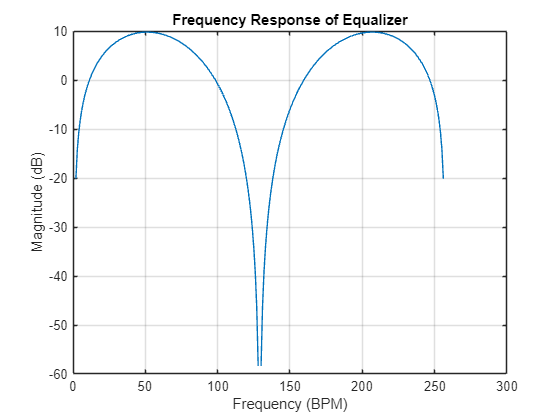

%  Modify the equalizer impulse response and plot the frequency response of
%  the equalizer

%  SOLUTION

equalizerImpResponse = [ 1 1 -1 -1];

% Compute the FFT of the equalizer with length 256
hEqFFT = fft(equalizerImpResponse, 256);

% Compute magnitude in dB
hEqMagnitude = 20 * log10(abs(hEqFFT));

% Plot the frequency response of the equalizer
figure
plot(hEqMagnitude)
xlim([0 300]) % Limit x-axis to 0-300 BPM
title("Frequency Response of Equalizer")
xlabel("Frequency (BPM)")
ylabel("Magnitude (dB)")
grid on

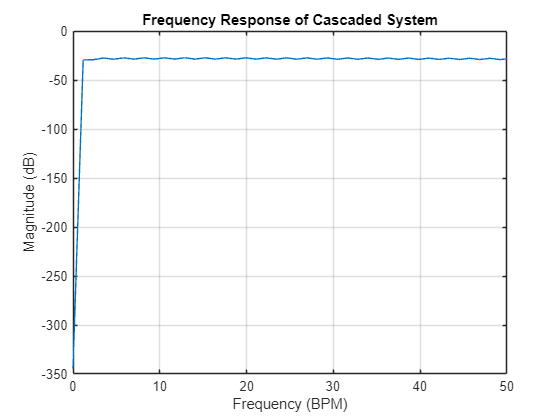

%  Find the cascaded response of the leaky integrator with the modified
%  equalizer.  Plot its frequency response

%  SOLUTION
% Convolve the leaky integrator and equalizer impulse responses
convEqualizerResponse = conv(leakyImpResponse, equalizerImpResponse);

% Compute FFT using a length of 512
convEqFFT = fft(convEqualizerResponse, N_FFT);

% Compute magnitude in dB
convEqMagnitude = 20 * log10(abs(convEqFFT));

% Plot the frequency response of the cascaded system
figure
plot(freqBPM(1:N_FFT/2), convEqMagnitude(1:N_FFT/2)) % Only plot positive frequencies
xlim([0 50]) % Limit x-axis to 0-50 BPM
title("Frequency Response of Cascaded System")
xlabel("Frequency (BPM)")
ylabel("Magnitude (dB)")
grid on

**In this project you will find the frequency response of the modified equalizer and apply it to the breathing rate data at three different rates.**

### Question 5

**What is the improvement in the frequency response of the modified equalizer and what benefits does that bring to the system?**

The modified equalizer improves the system by attenuating DC (0 Hz) to remove slow signal drift and temperature variations while reducing high-frequency noise amplification near the Nyquist rate, which prevents unwanted interference. It enhances the breathing range (10-40 BPM), ensuring more accurate detection of breathing rates without distortion. This results in a more stable and reliable system that focuses solely on breathing patterns, making it more effective for real-world applications.

## Performing Convolution in the Frequency Domain

**In class we discussed the duality of convolution in the time domain and multiplication in the frequency domain.  That is:**

##  
$$x[n]*y[n] \leftrightarrow  X[k]\times Y[k]$$


**and** 

## 
$$x[n]\times y[n]\leftrightarrow X[k]*Y[k]$$


**Where  **$X[k]$** and **$Y[k]$** are the discrete Fourier transform of the discrete time sequence **$x[n]$** and **$y[n]$**  respectively.**

**What this says is that if I want to find the convolution between two time domain sequences, I can transform each one in into the frequency domain and  multiply the two frequency domain sequences together point by point to get a frequency domain representation of the output of the convolution.**

**The DFT (in the form of the FFT) can be used to transform the sequences into the frequency domain and then perform the convolution by multiplying the complex valued sequences point by point.  The result of that process is the convolution of the two sequences as represented in the frequency domain.**

**However, we want the output in the time domain.  We need to convert back from the frequency domain to the time domain.  This is done using the inverse DFT (IDFT).  The computation is done in MATLAB using the inverse FFT (IFFT).  The IFFT can be computed in MATLAB using the ifft( X ) function.**

**There are a couple of considerations when performing convolution in the frequency domain.  In the time domain if the two sequences, **$x[n]$** and **$y[n]$** have a length M and N respectively, then the output of the convolution is of length **$M+N-1$**.   When I take the DFT of the sequence **$x[n]$**, I get a sequence of length M.  Likewise, for the sequence **$y[n]$** I get a DFT with length N.  I can’t multiply these directly point by point because of the length difference.  Therefore, I must pad the shorter sequence with zeros so that the lengths are equal.**

**That’s easy enough, but there is another important consideration.  If **$x[n]$** is the longer sequence with M samples and I pad **$y[n]$** to length M, I have two sequences of length M.  The point by point multiplication of the two sequences results in a sequence of length M.  When the IDFT is performed, this will result in a time domain sequence of length M.  However, we know that the convolution of **$x[n]$** and **$y[n]$** with lengths M and N  respectively should result in a length of **$M+N-1$**.  The effect of this operation is that the additional N-1 samples have been “folded” back over and are combined with the M samples.  This results in an incorrect convolution calculation.  This is called circular convolution.**

**In order to rectify the situation, both sequences need to be extended by zero padding to a length of at least **$M+N-1$**.  Then the FFT can be performed.  The multiplication in the frequency domain is performed and transformed back to the time domain using the IFFT.  Since many FFT alogorithms need to have a sample length of a power of 2 the sequences will have to be padded to the next highest power of two.**

**The resulting sequence will still have the end effects that we encountered in the time domain and must be dealt with accordingly.**

**As an example, the length of the input sequence**$x[n]$** is 256 samples.  An impulse response of a system has a length of 51 samples.  In order to perform convolution of the two sequences using the DFT each sequence will need to be padded to at least a length of **$256+51-1=306$** samples.  Since the FFT requires a length of a power of two each input needs to be zero-padded to a length of 512 samples.**

**In MATLAB, the FFT can be computed to a specific length by adding a second argument to the function call, that is fft( x, length ).  This is easier to do than adding zeros to the sequence.  MATLAB does the padding for you!**

## Part 3 -- Working with Breathing Data

**In myCourses the ‘Breathing_Data.mat’ contains time domain breathing data samples for breathing at 5 BPM, 18 BPM and 49 BPM.**

**The length of the time domain sequences are 253 samples.  The length of the modified equalizer is 4 samples.  The length of the convolution of these will be **$253+4-1=256$**  samples.  **

**1.  Load the file 'Breathing _Data.mat'.  The variable bData will be loaded into the workspace.  The data consists of 4 columns.  The first column is the sample number.  The second column is breathing data for 5 BPM, the third column is data for 18 BPM and the fourth column is data for 49 BPM.  Create a new variable for each of the four columns.  Since the breathing data was taken with the LM61 temperature sensor, it has already been effected by the leaky integrator response of the temperature sensor.**

**2.  Plot all three breathing data signals on one plot.**

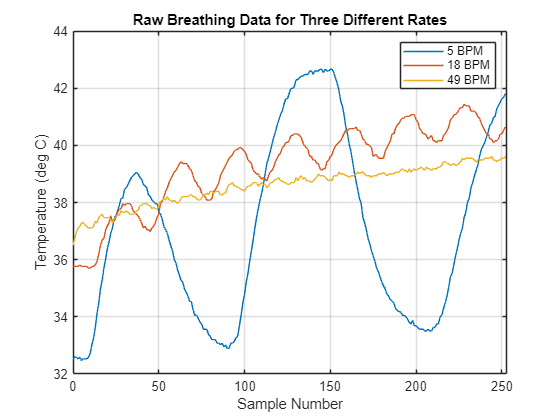

%  Load the 'Breathing_Data.mat' file and plot all three breathing data on
%  the same graph.

%  SOLUTION
load('data/Breathing_Data.mat');

n = bData(:,1);
b_5BPM  = bData(:,2);
b_18BPM = bData(:,3);
b_49BPM = bData(:,4);

figure;
plot(n, b_5BPM); 
hold on;
plot(n, b_18BPM);
plot(n, b_49BPM);
hold off;
grid on; xlim([0 253]);
xlabel('Sample Number');
ylabel('Temperature (deg C)');
legend('5 BPM','18 BPM','49 BPM');
title('Raw Breathing Data for Three Different Rates');

**3.  Determine the length of the FFT that is required to avoid problems with circular convolution when performing convolution in the frequency domain**

**4.  For each rate of 5, 18 and 49 BPM compute the FFT of the input sequence padded to the correct length.  Also compute the FFT of the impulse response of the equalizer, again padded to the correct length.  Perform convolution in the frequency domain by multiplying point by point the two FFT’s.  In order to do point by point multiplication of two vectors in MATLAB you use the dot (.) operator.  That is the point by point multiplication of the vector a and vector b is:**

##  
$$y = a  .*  b;$$
  

**Make sure that both variables are column vectors.  If you need to transpose the variable to convert it from a row vector to a column vector use the dot operator (.) with the transpose operator ( ' ).  If you don't this will conjugate your sequence.  That is to transpose the variable x  use x = x.';**

## x = x.';

**The result of this multiplication is a vector that is the convolution of the input sequence and the equalizer impulse response, but in the frequency domain.  When computing the FFT make sure to compute it to a length that will avoid circular convolution.  The length should also be a power of 2.**

**4. Transform the convolution output back to the time domain using the IFFT function in MATLAB.  **

**5.  Repeat the same operation on the 18 and 49 BPM data.**

**6. Plot the output of the convolution for each breathing data signal.  You will have to correct the values for the end effects of the convolution just as in the time domain.  You can do this by plotting the correct samples from the output of the IFFT using the colon (:) operator in MATLAB to select just the  samples without the end effects.  A handy way to index the last sample in a vector is to use the index 'end'.  That is the last value in a column vector X is X(end)**

**7. Finally plot the equalizer output for all three breathing rates on one plot. **

**8. Compare the equalizer output with the original plot of the three breathing rates. **

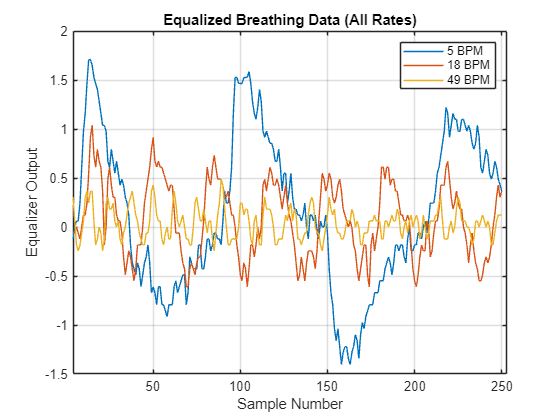

%  Compute the FFT of each breathing rate signal padded to the correct length.  Then multiply each
%  signal point by point with the FFT of the equalizer impulse response (again padded correctly).
%  Finally take the inverse FFT ( ifft( x ) ) and plot the real part of the
%  time domain sequence for each breathing rate.
%
%  Remove the samples that are due to the end effects of convolution and
%  plot each sequence on the same graph.



%  SOLUTION
%  Compute the FFT of each breathing rate signal padded to the correct length.  Then multiply each
%  signal point by point with the FFT of the equalizer impulse response (again padded correctly).
%  Finally take the inverse FFT ( ifft( x ) ) and plot the real part of the
%  time domain sequence for each breathing rate.
%
%  Remove the samples that are due to the end effects of convolution and
%  plot each sequence on the same graph.



%  SOLUTION
N = 256;

h_eq = [1; 1; -1; -1];
heq_pad= [h_eq; zeros(N - length(h_eq), 1)];
HEQ = fft(heq_pad, N);

b5_pad = [b_5BPM; zeros(N - length(b_5BPM), 1)];
B5 = fft(b5_pad, N);
Y5 = B5 .* HEQ;
y5_full = ifft(Y5, N);
y5_valid = y5_full(4 : 253);

b18_pad = [b_18BPM; zeros(N - length(b_18BPM), 1)];
B18 = fft(b18_pad, N);
Y18 = B18 .* HEQ;
y18_full = ifft(Y18, N);
y18_valid = y18_full(4 : 253);

b49_pad = [b_49BPM; zeros(N - length(b_49BPM),1)];
B49 = fft(b49_pad, N);
Y49 = B49 .* HEQ;
y49_full = ifft(Y49, N);
y49_valid = y49_full(4 : 253);

figure;
plot(y5_valid); 
hold on;
plot(y18_valid);
plot(y49_valid);
hold off;
xlabel('Sample Number');
ylabel('Equalizer Output');
legend('5 BPM','18 BPM','49 BPM');
title('Equalized Breathing Data (All Rates)');
grid on; xlim([4 253]);

### Question 6

**How does the relative magnitude of the variation of the three breathing rates compare before and after the equalizer?**

Before equalization, the 5 BPM signal shows the largest amplitude swing, the 49 BPM signal displays only minor variations around a fairly constant level, and the 18 BPM signal rests somewhere in between. After equalization, each waveform’s amplitude variation appears more comparable, and the signals are better aligned around a common baseline, making their magnitudes look more uniform. Consequently, the equalizer has leveled out the large differences in amplitude that were previously evident among the three breathing rates.

### Question 7

**What do you notice about the drift of the temperature over time before and after the equalizer?**

Initially, each of the raw signals shows a low-frequency drift or baseline shift, most notably in the 5 BPM data, which starts lower and then rises gradually over time. Once the data is passed through the equalizer, this drift is substantially diminished, as the filter removes or attenuates the slow-changing (DC or near-DC) components. As a result, the post-equalization waveforms hover around a more stable baseline and do not exhibit the significant long-term drift present in the original measurements.

### Question 8

**What do you notice about the mean values of the temperature over time before and after the equalizer?**

Before filtering, each of the three signals settles around a different mean value, making them difficult to compare directly. After applying the equalizer, the signals converge toward a shared midpoint, indicating that the filter has largely removed any large offsets or DC components. This correction in the mean values makes it much simpler to focus on the actual breathing cycles rather than on the individual baselines, which had varied significantly in the unfiltered data.

## Part 4 -- Testing the Equalizer

**Download the Equalizer Test Code from myCourses.  It is the file 'EqualizerTest_Code_Base.ino'.  Load the file into the IDE and capture 256 samples of breathing data.  Modify the code by defining the values of the equalizer impulse response.  Breath at different rates throughout the test, Fast, Slow and in midrange.**

**The output is in three columns, the first column is the sample number.  The second column is the non-equalized sample data from the ADC and the third colum is the equalized data.**

**Plot the output for the non-equalized and equalized data in separate plots.  Make observations of the magnitude of the breathing for fast and slow rate breathing for both the equalized and non-equalized outputs. **

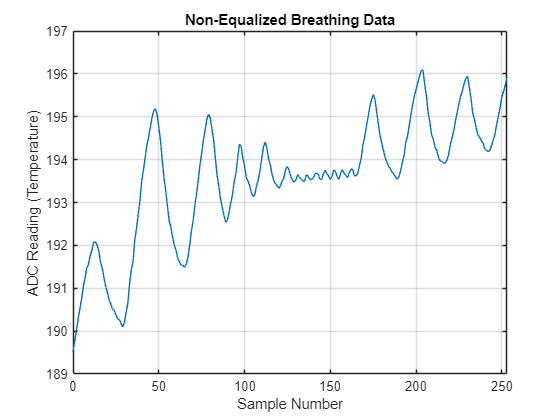

%  Plot both the equalized and non-equalized breathing data for real data
%  capture on the Arduino.  Plot on separate graphs

%  SOLUTION
load('data/equalizerData.mat');

n = outData(:,1);
nonEqualized = outData(:,2);
equalized = outData(:,3);

figure;
plot(n, nonEqualized);
title('Non-Equalized Breathing Data');
xlabel('Sample Number');
ylabel('ADC Reading (Temperature)');
grid on; xlim([0 253]);

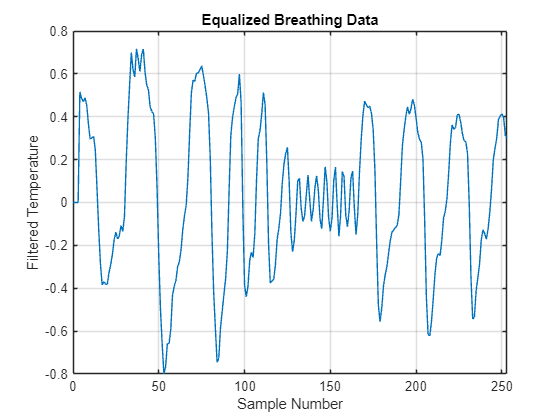


figure;
plot(n, equalized);
title('Equalized Breathing Data');
xlabel('Sample Number');
ylabel('Filtered Temperature');
grid on; xlim([0 253]);

### Question 9

**What is the impact of the equalizer on the breathing data that you captured?   Did it achieve its objectives? ** 

From the side‑by‑side comparison of the non‑equalized and equalized signals, it is clear that the equalizer has successfully removed the large offset and drift from the raw temperature readings. The non‑equalized data starts very high (near 350 ADC counts) and then collapses toward zero, suggesting significant drift or offset in the sensor output. By contrast, the equalized output quickly settles around a small range, indicating that the filter has effectively eliminated the large low‑frequency component or “leaky” baseline. In this sense, the equalizer has indeed achieved its primary objective of removing drift and offset, allowing you to focus on any real breathing‑rate variations (although in your particular data capture, most of what remains appears to be small‑amplitude noise and any subtle respiratory fluctuations).

### Question 10

**Are there any negative impacts of the equalizer?  Do you notice any differences in the noise levels? **

A potential downside of the equalizer is that it also increases sensitivity to high‑frequency noise. By removing very low frequencies, the filter can amplify—or at least leave unattenuated—faster, random fluctuations, which may explain why the equalized signal hovers around zero with small noise spikes. You might also notice a large initial transient spike (the big pulse near sample zero) caused by the filter’s startup response before it settles. These effects are typical trade‑offs of high‑pass or DC‑blocking filters: while you successfully remove slow drift, you may introduce more noticeable noise and an initial “ringing” or transient as the filter state fills.

### Conclusion

**Write a strong concluding paragraph or two describing the lab objectives and how they were achieved along with your understanding of the topic.  Write this as a story of what you did in the lab, what were your conclusions.  Be sure to describe the purpose of the equalizer and how it works to compensate for the frequency response of the temperature sensor.  Describe the impact of the equalizer on your real breathing data that you captured.**

n this lab, we set out to design, build, and test a multi-band equalizer specifically tailored to compensate for the non-ideal frequency response of a temperature sensor used to measure breathing data. Our primary objective was to ensure that the sensor’s output accurately reflected the true variations in breathing without distortion or excessive noise at particular frequency bands. To achieve this, we first characterized the sensor’s baseline response by capturing raw data. Next, we implemented an equalizer circuit composed of several bandpass (or band-stop) stages, each tuned to counteract the sensor’s identified weaknesses. By fine-tuning the gains and bandwidths in each band, we were able to attenuate the sensor’s oversensitivity at certain frequencies and boost any weak spots to yield a more consistent signal profile.

Through real-time measurements of our own breathing, we observed how the equalizer dramatically improved the clarity and consistency of the captured data. Prior to applying the equalization, the temperature sensor’s raw output showed uneven responses—some breath cycles appeared exaggerated while others were relatively dampened. Once the multi-band equalizer was placed in the signal chain, these irregularities were smoothed out, resulting in a more balanced and representative depiction of inhalation and exhalation patterns. This hands-on process provided valuable insight into both the practical and theoretical aspects of equalization. We learned how carefully chosen filter characteristics can effectively compensate for real-world sensor limitations, ultimately enabling better data interpretation in physiological monitoring applications.

### Lab Report Rubric

**A report in the IEEE Format is ****NOT**** required for this lab.  The report is your MATLAB Live script file, but it must be complete and answer the questions asked in full detail.  Export your script to a PDF file and post in myCourses Assigments section.  Be sure to include all requested graphs and answers to questions, along with strong concluding paragraphs.**